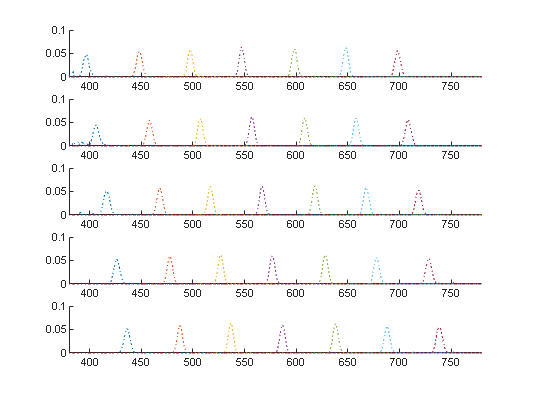

load('char.mat')


clf
hold on
spec_min = spd_min;
spec_max = spd_max;

for comb_i=1:5
    spec_comb = s_measured_all{comb_i}.amplitude;
    spec_comb_net = spec_comb - spec_min;
    
    refl_comb = spec_comb_net ./ spec_max;
    refl_comb = max(0,refl_comb);

    wl_comb = wl_measured_all{comb_i};

    % visualize
    subplot(5,1,comb_i)
    hold on
    %plot(380:780,refl_comb)
    axis([380 780 0 0.1])

    for j = 1:7
        wl_estimated = 400+10*(comb_i-1)+50*(j-1);
        refl_isolated = bandpass_at(refl_comb,wl_estimated);
        plot(380:780,refl_isolated,':')

%        wl_j = wl_comb(j);
%        plot(wl_j,0.05,'or')
    end
end

function spec_isolated = bandpass_at (spec,wl_estimated)
    bandwidth = 25;

    % find the max around wl_estimated +/- bandwidth
    wlidx = wl_estimated - 380+1;
    wlidx_start = wlidx-bandwidth;
    wlidx_end = wlidx+bandwidth;
    wlidx_start = max(1,wlidx_start);
    wlidx_end = min(401,wlidx_end);

    spec_temp = spec;
    spec_temp([1:wlidx_start-1 wlidx_end+1:end]) = 0;
    [M I] = max(spec_temp);

    % re-center
    wlidx = I;
    wlidx_start = wlidx-bandwidth;
    wlidx_end = wlidx+bandwidth;
    wlidx_start = max(1,wlidx_start);
    wlidx_end = min(401,wlidx_end);

    spec_isolated = spec;
    spec_isolated([1:wlidx_start-1 wlidx_end+1:end]) = 0;

end